# Práctica 1 - CARMEN GALLARDO Y PABLO MENDIE

## Definición de variables

Vamos a realizar el modelo de una supuesta propagación de una enfermedad. Definimos las siguientes variables:


$$\begin{array}{l}
\mathbf{Pi}:\mathrm{Nº}\;\mathrm{de}\;\mathrm{Personas}\;\mathrm{infectadas}\\
\;\Pr :\mathrm{Nº}\;\mathrm{de}\;\mathrm{Personas}\;\mathrm{recuperadas}\\
\mathbf{Población}:\mathrm{Nº}\;\mathrm{total}\;\mathrm{de}\;\mathrm{personas}\;\\
\mathbf{Psuscep}:\mathrm{Nº}\;\mathrm{Personas}\;\mathrm{suceptibles}\\
\mathbf{TIC}:\mathrm{Tasa}\;\mathrm{de}\;\mathrm{Infencción}\;\mathrm{por}\;\mathrm{Contacto}\to N\left(0\ldotp 4,0,1\right)\\
\mathbf{TRI}:\mathrm{Tasa}\;\mathrm{de}\;\mathrm{Recuperación}\;\mathrm{de}\;\mathrm{la}\;\mathrm{Infección}\to \beta \left(4,1\right)
\end{array}$$


clc, clear, clf
pi = 10;
pr = 0;
poblacion = 1000;
psuscept = poblacion - pi;
distTIC = [0.4 0.1];
distTRI = [4 1];
Fin = 25; %tiempo de parada
T = 1;

## Mecanismo de transición (Ecuaciones en difrencia)

Para obtener los mecanismos de transición que existen, vamos a tener en cuenta la variación de la población infectada y la variación de la población recuperada. 

Para calcular la variación de población infectada, tenemos que tener en cuenta la población susceptible de infectarse, es decir, la población total sin contar las personas ya infectadas y las que ya han pasado la infección Por otro lado hay que tener en cuenta las personas que se van a recuperar ese día. Para la variación de población recuperada simplemente hay que tener en cuenta las personas que están infectadas. Las ecuaciones quedarían de la siguiente manera:


$$\Delta p_i =\mathrm{TIC}*\left(\mathrm{población}-\left(p_i -p_r \right)\right)-\mathrm{TRI}*p_i$$



$$\Delta \mathrm{pr}=\mathrm{TRI}*p_i$$


Sabemos tambien lo siguiente:


$$p_{\mathrm{suscep}} =\;$$

$$\left(\mathrm{población}-\left(p_i -p_r \right)\right)$$


Ahora, para obtener las ecuaciones en diferencia sustituimos la variación de la siguiente manera:


$$\Delta p_i =\frac{{\mathrm{pi}}_{n+1} -{\mathrm{pi}}_n }{\Delta t}$$



$$\Delta p_i =\frac{{\mathrm{pr}}_{n+1} -{\mathrm{pr}}_n }{\Delta t}$$


Suponemos que $\Delta t$ es igual a 1, porque queremos analizar el modelo día a día. De esta manera nos quedan las siguientes ecuaciones en difrencia: 


$${\mathrm{pi}}_{n+1} =\mathrm{TIC}*{\mathrm{psuscep}}_n -\mathrm{TRI}*{\mathrm{pi}}_n +{\mathrm{pi}}_n$$



$${\mathrm{pr}}_{n+1} =\mathrm{TRI}*{\mathrm{pi}}_n +{\mathrm{pr}}_n$$



$${\mathrm{psucept}}_{n+1} ={\mathrm{psuscep}}_n -{\mathrm{pi}}_n -{\mathrm{pr}}_n$$


## Diagrama de Flujo

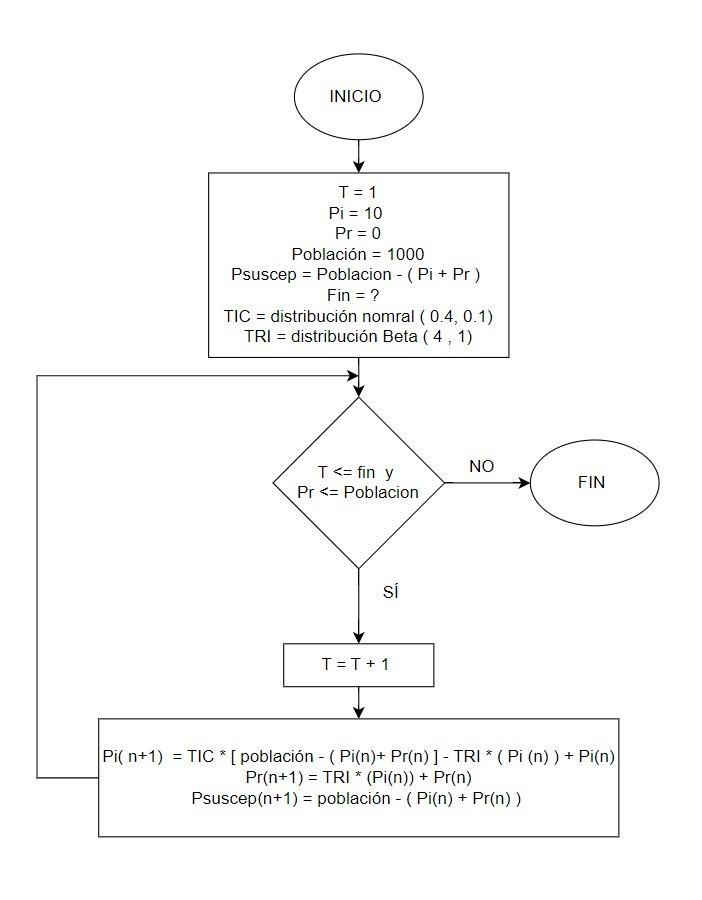

## Traza

Para analizar que el diagrama de flujo es correcto, realizamos la traza con excel (suponemos que TIC y TRI son 0.4 y 0.8 respectivamente):

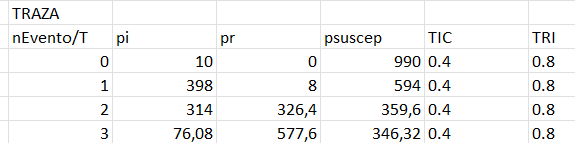

Observamos que dan valores con sentido.

## Solución gráfica

Para calcular la solución grafica utilizamos una función qeu replica el diagram de flujo

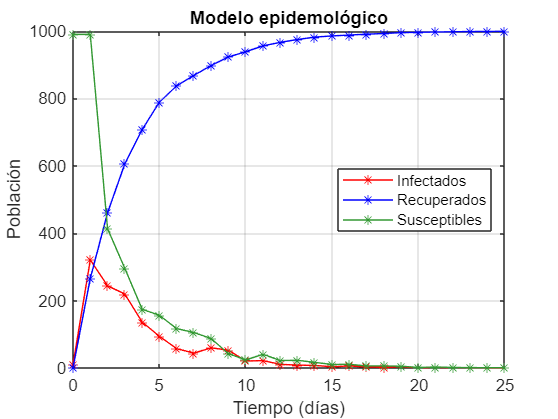

[vectorpi, vectorpr,vectorsuscep] = infeccion (T, Fin,poblacion,psuscept,pi,pr, distTIC, distTRI );
plot(T-1:Fin,vectorpi, '-*r')
hold on
plot(T-1:Fin,vectorpr, '-*b')
hold on
plot(T-1:Fin,vectorsuscep, '-*', 'Color',[0.2,0.6,0.2])
xlabel("Tiempo (días)")
ylabel("Población")
title("Modelo epidemológico")
legend('Infectados', 'Recuperados','Susceptibles', 'Location', 'east')
grid on
hold off

Al observar la gráfica vemos que el sistema tiende a la estabilidad, donde la población de recuperados  tiende a la población total y el número de infectados tiende a cero. Esto tiene sentdio ya que la toda la población acabará pasando la infección.

function [vectorpi, vectorpr, vectorsuscep] = infeccion (T, Fin,poblacion,psuscep,pi,pr, distTIC, distTRI )
    
    vectorpi = pi;
    vectorpr = pr;
    vectorsuscep = psuscep;
    %Rutina de parada
    while T<= Fin && pr<=poblacion 
        %Rutina de tiempo
        T = T + 1;
        
        %Rutina de evento
        TIC = normrnd(distTIC(1),distTIC(2)); %al randomizar estos datos pueden dar valores negativos lo cual genera infectados negativos (afecta tambien a susceptibles)
        TRI = betarnd(distTRI(1),distTRI(2));
        psuscep = poblacion- pi  - pr;
        pi = TIC*(psuscep) - TRI*pi + pi; 
        pr = TRI*pi + pr;
        

        vectorpi = [vectorpi pi];
        vectorpr = [vectorpr pr];
        vectorsuscep = [vectorsuscep psuscep];
    end    
end